clc; clear; close all;

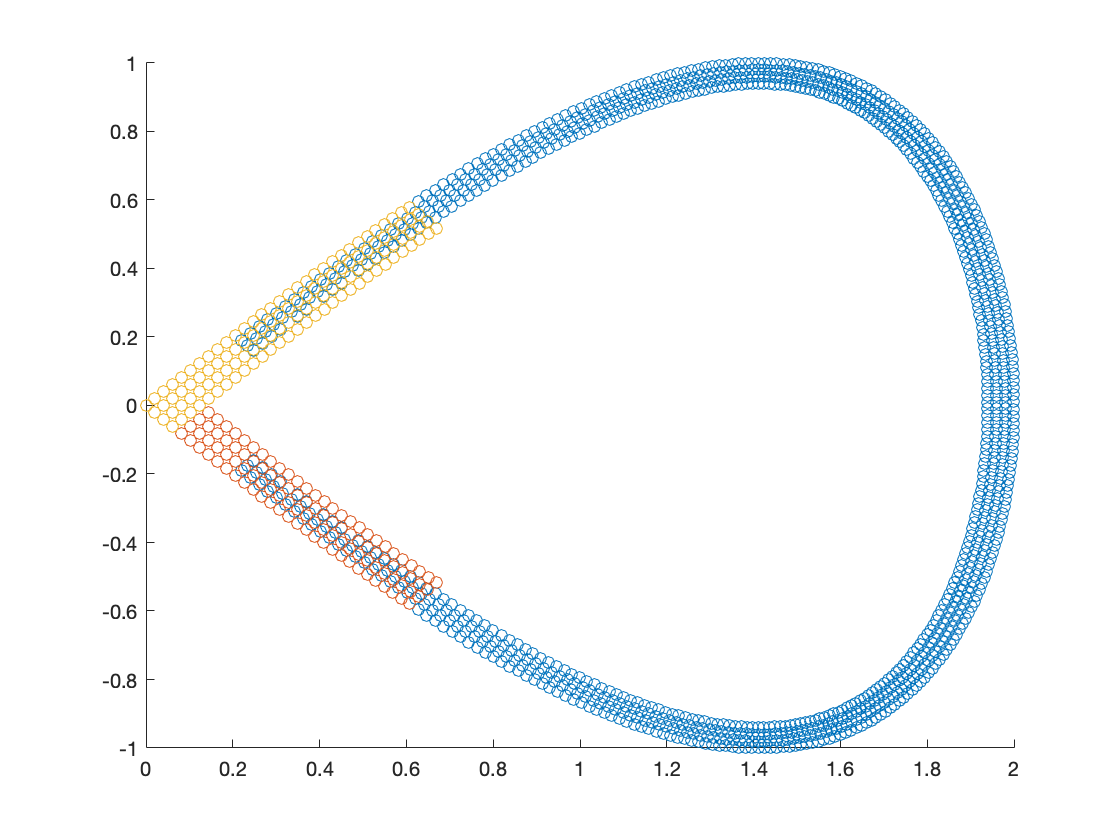

start first pass
Elapsed time is 2.879808 seconds.
construct nan map
start first pass
Elapsed time is 0.294835 seconds.
construct nan map
start first pass
Elapsed time is 0.292556 seconds.
construct nan map
start first pass
Elapsed time is 0.327406 seconds.
construct nan map
fc error: 0.0036053


% setting up domain
l_1 = @(theta) 2*sin(theta*pi);
l_2 = @(theta) -sin(theta*2*pi);
l_1_prime = @(theta) 2*pi*cos(theta*pi);
l_2_prime = @(theta) -2*pi*cos(theta*2*pi);
l_1_dprime = @(theta) -2*pi^2*sin(theta*pi);
l_2_dprime = @(theta) 4*pi^2*sin(theta*2*pi);

d = 4;
C = 27;
n_r = 6;
M = d+3;

h = 0.02;

n_frac_C = 1/10;

if(exist(['FC_data/A_d',num2str(d),'_C', num2str(C), '_r', num2str(n_r), '.mat']) == 0 | ...
   exist(['FC_data/Q_d',num2str(d),'_C', num2str(C),  '_r', num2str(n_r), '.mat']) == 0)
    disp('FC data not found. Generating FC operators... \n');
    generate_bdry_continuations(d, C, C, 12, 20, 4, ...
        256, n_r);
end

load(['FC_data/A_d',num2str(d),'_C', num2str(C), '_r', num2str(n_r), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(C),  '_r', num2str(n_r), '.mat']);

A = double(A);
Q = double(Q);

curve_seq = Curve_seq_obj();
curve_seq.add_curve(l_1, l_2, l_1_prime, l_2_prime, l_1_dprime, l_2_dprime, 0, n_frac_C, n_frac_C, 0, 0, h);

f = @(x, y) 4 + (1 + x.^2 + y.^2).*(sin(2.5*pi*x - 0.5) + cos(2*pi*y - 0.5));
eps_xi_eta = 1e-13;
eps_xy = 1e-13;

[R_c, interior_patches, fc_patches] = FC2D(f, h, curve_seq, eps_xi_eta, eps_xy, d, C, n_r, A, Q, C, A, Q, M);

interior_patch_meshes = curve_seq.construct_patches(@(x, y) x*0+1, d, eps_xi_eta, eps_xy);

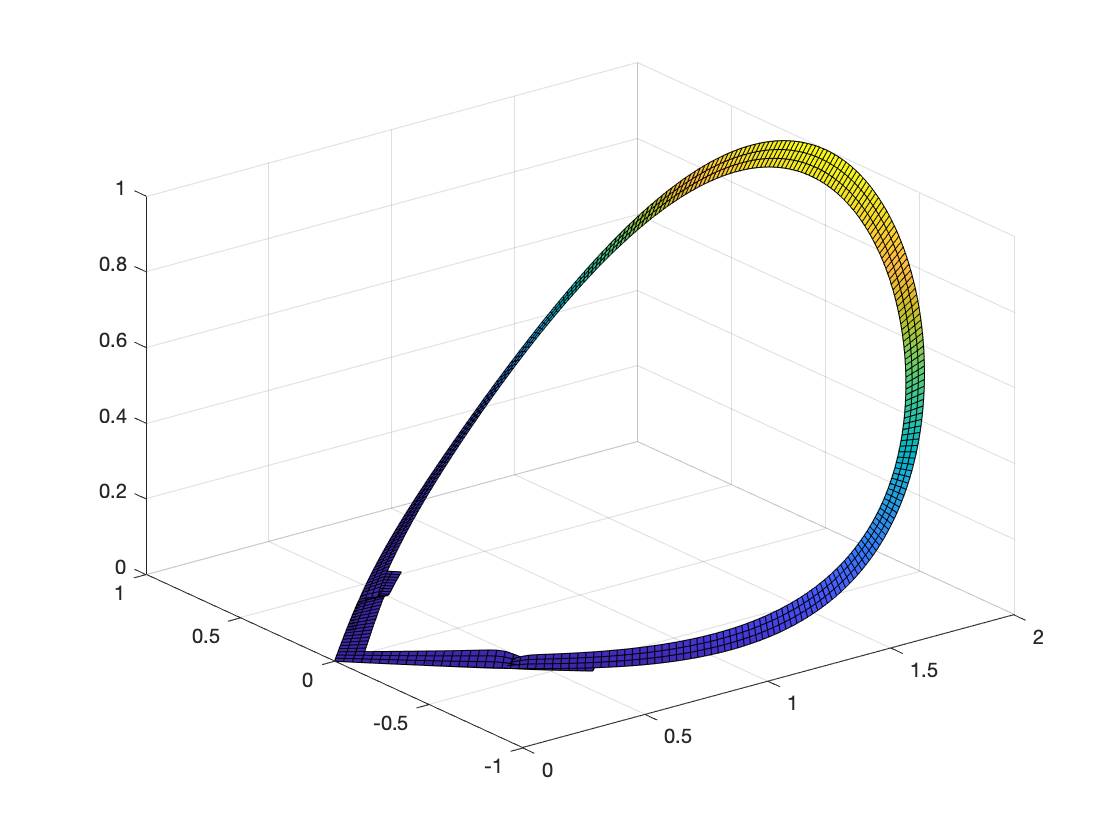


p_field = @(x, y) (x.^2-y.^2)./4;
R_p = R_cartesian_mesh_obj(R_c.x_start, R_c.x_end, R_c.y_start, R_c.y_end, h, R_c.boundary_X, R_c.boundary_Y);
p_interior = p_field(R_c.R_X(R_c.in_interior), R_c.R_Y(R_c.in_interior));

p_patches = cell(length(interior_patch_meshes));
for i = 1:curve_seq.n_curves
    S_patch = interior_patch_meshes{2*i-1}.copy_patch;
    C_patch = interior_patch_meshes{2*i}.copy_patch;
    
    [X_S, Y_S] = S_patch.Q.xy_mesh;
    [X_L, Y_L] = C_patch.L.xy_mesh;
    [X_W, Y_W] = C_patch.W.xy_mesh;
    
    S_patch.Q.f_XY = p_field(X_S, Y_S).*interior_patch_meshes{2*i-1}.Q.f_XY;
    C_patch.L.f_XY = p_field(X_L, Y_L).*interior_patch_meshes{2*i}.L.f_XY;
    C_patch.W.f_XY = p_field(X_W, Y_W).*interior_patch_meshes{2*i}.W.f_XY;
    
    p_patches{2*i-1} = S_patch;
    p_patches{2*i} = C_patch;
end

figure;
surf(X_S, Y_S, S_patch.Q.f_XY)
hold on;
surf(X_W, Y_W, C_patch.W.f_XY)
surf(X_L, Y_L, C_patch.L.f_XY)


FC2D_patches(p_patches, R_p, p_interior, curve_seq, d, C, n_r, A, Q, C, A, Q, M)

start first pass
Elapsed time is 2.927301 seconds.
construct nan map
start first pass
Elapsed time is 0.296565 seconds.
construct nan map
start first pass
Elapsed time is 0.297002 seconds.
construct nan map
start first pass
Elapsed time is 0.331788 seconds.
construct nan map


div_p =    -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000 

ans = 0.0152

ans = 1.7572e-04

ans = 0.0145

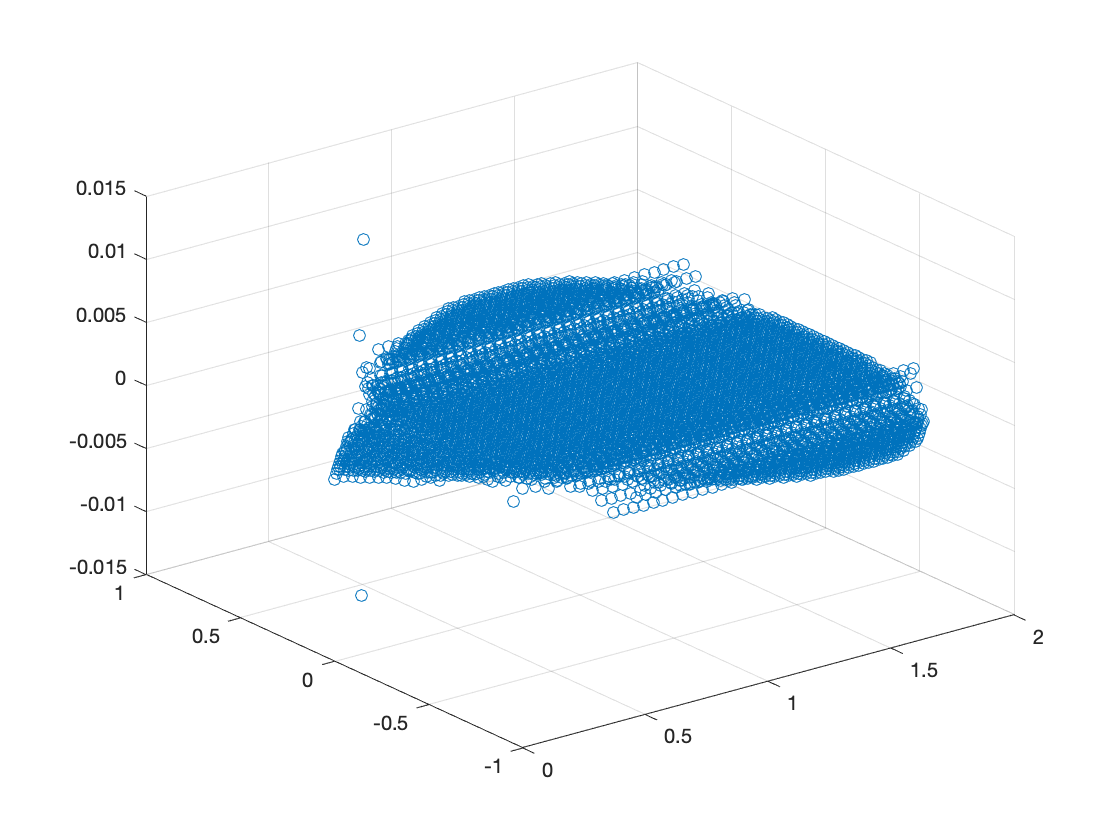

Unable to resolve the name R.R_X.

[u_x, u_y] = R_p.grad(R_p.f_R);

p_boundary = @(theta) cos(theta*2*pi).^2;

f_numeric = laplace_solver_teardrop(p_boundary, R.x_start, R.x_end, R.y_start, R.y_end, 0.05, fc_patches, 1e-5);
